# Getting the auto/cross covariance function from an AR model

## Introduction

In this tutorial you will learn how to estimate the autocovariance function of a univariate random process defined by an AR model. The autocovariance function is a discrete function that depends on the lag $m$, $\gamma^{AR}[m]$.

The dataset employed in this tutorial is '*database/case_03_AR*', which includes a restricted AR model employed in Section 3.1 of** [1]**. In this tutorial, figure 5 of the mentioned reference is reproduced.

**[1]** Gallego-Castillo, C. et al., A tutorial on reproducing a predefined autocovariance function through AR models: Application to stationary homogeneous isotropic turbulence, Stochastic Environmental Research and Risk Assessment. DOI: 10.1007/s00477-021-02156-0 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

M = 20;   % máximum lag considered for gamma 


%%% Plot parameters
font_size       = 16;
figure_position = [0 0 1000 400];

Load the dataset. It consists of a restricted AR model. Check the fields required by function `get_gamma_AR`. For details related to the fields of these objects, see functions `initialise_`AR.

load case_03_AR AR

fprintf('j_vector is [%d, %d, %d] \n', AR.restricted_parameters.j_vector)

j_vector is [1, 2, 5] 


fprintf('a_vector is [%.1f, %.1f, %.1f] \n', AR.restricted_parameters.a_vector)

a_vector is [1.2, -0.5, 0.1] 


fprintf('b is %.1f \n',AR.restricted_parameters.b)

b is 0.5 


Initialise a `gamma_fun` object with the fields required by function `get_gamma_data`.

[gamma_fun] = initialise_gamma('M', M);

Compute the autocovariance function of the AR model.

[gamma_fun] = get_gamma_AR (AR, gamma_fun);

Plot the obtained autocovariance function.

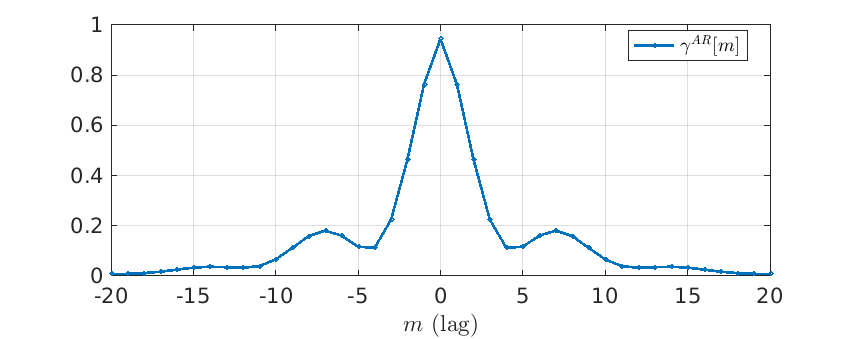

figure

x = gamma_fun.xlag_values;
y = gamma_fun.y_values;
plot(x,y,'O-','LineWidth',2,'MarkerSize',3)

grid on
legend({'$\gamma^{AR}[m]$'},...
        'Interpreter','latex',...
        'Location','best')
xlabel('$m$ (lag)','Interpreter','latex')

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- Note that the *x*-axis is for lags, which are stored in field `gamma_fun.xlag_values`. The field `gamma_fun.x_values` is for cases in which the sampling time, $\Delta t$, is known, so that the autocovariance function can be represented as a function of time (or space).